# 딥러닝 신경망 아키텍처 만들기

다음 속성을 사용하여 딥러닝 신경망의 계층을 만드는 스크립트:

스크립트를 실행하여 작업 공간 변수 `lgraph`에 계층을 만듭니다.

자세한 내용은 [심층 신경망 디자이너에서 MATLAB 코드 생성](matlab:helpview('deeplearning','generate_matlab_code'))을(를) 참조하십시오.

MATLAB에서 2020-08-11 08:54:58에 자동 생성됨

## 계층 그래프 생성

신경망의 계층을 담을 계층 그래프 변수를 만듭니다.

lgraph = layerGraph();

## 계층 분기 추가

계층 그래프에 신경망의 분기를 추가합니다. 각 분기는 계층으로 구성된 선형 배열입니다.

tempLayers = [
    imageInputLayer([360 480 3],"Name","inputImage")
    
    convolution2dLayer([7,7],64,"Name","encoder1_conv1","BiasLearnRateFactor",0,"Padding",'same')
    batchNormalizationLayer("Name","encoder1_bn_1")
    reluLayer("Name","encoder1_relu_1")
    
    maxPooling2dLayer([2 2],"Name","MP1","HasUnpoolingOutputs",true,"Stride",[2 2])
    
    convolution2dLayer([7,7],128,"Name","encoder1_conv2","BiasLearnRateFactor",0,"Padding",'same')
    batchNormalizationLayer("Name","encoder1_bn_2")
    reluLayer("Name","encoder1_relu_2")
    
    maxPooling2dLayer([2 2],"Name","MP2","HasUnpoolingOutputs",true,"Stride",[2 2])
    ];

lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([7,7],256,"Name","encoder2_conv1","BiasLearnRateFactor",0,"Padding",'same')
    batchNormalizationLayer("Name","encoder2_bn_1")
    reluLayer("Name","encoder2_relu_1")
    
    maxPooling2dLayer([2 2],"Name","MP3","HasUnpoolingOutputs",true,"Stride",[2 2])
    
    convolution2dLayer([7,7],512,"Name","encoder2_conv2","BiasLearnRateFactor",0,"Padding",'same')
    batchNormalizationLayer("Name","encoder2_bn_2")
    reluLayer("Name","encoder2_relu_2")
    
    convolution2dLayer([7,7],512,"Name","decoder2_conv2","BiasLearnRateFactor",0,"Padding",'same')
    batchNormalizationLayer("Name","decoder2_bn_2")
    
    convolution2dLayer([7,7],256,"Name","decoder2_conv1","BiasLearnRateFactor",0,"Padding",'same')
    batchNormalizationLayer("Name","decoder2_bn_1")'
    
    maxUnpooling2dLayer("Name","MUP1")
    ];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([7,7],128,"Name","decoder1_conv2","BiasLearnRateFactor",0,"Padding",'same')
    batchNormalizationLayer("Name","decoder1_bn_2")
    
    maxUnpooling2dLayer("Name","MUP2")
    
    convolution2dLayer([7,7],64,"Name","decoder1_conv1","BiasLearnRateFactor",0,"Padding",'same')
    batchNormalizationLayer("Name","decoder1_bn_1")
    
    maxUnpooling2dLayer("Name","MUP3")
    
    convolution2dLayer([7,7],11,"Name","LastConv","BiasLearnRateFactor",0,"Padding",'same')
    softmaxLayer("Name","softmax")
    pixelClassificationLayer("Name","pixelLabels")];
lgraph = addLayers(lgraph,tempLayers);

% 헬퍼 변수 정리
clear tempLayers;

## 계층 분기 연결

신경망의 모든 분기를 연결하여 신경망의 그래프를 만듭니다.

lgraph = connectLayers(lgraph,"MP2/out","encoder2_conv1");
lgraph = connectLayers(lgraph,"MUP1/out","decoder1_conv2");

lgraph = connectLayers(lgraph,"MP1/indices","MUP3/indices");
lgraph = connectLayers(lgraph,"MP1/size","MUP3/size");
lgraph = connectLayers(lgraph,"MP2/indices","MUP2/indices");
lgraph = connectLayers(lgraph,"MP2/size","MUP2/size");
lgraph = connectLayers(lgraph,"MP3/indices","MUP1/indices");
lgraph = connectLayers(lgraph,"MP3/size","MUP1/size");

## 계층 플로팅

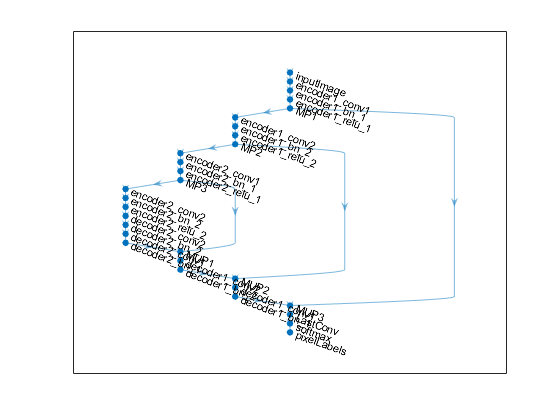

plot(lgraph);